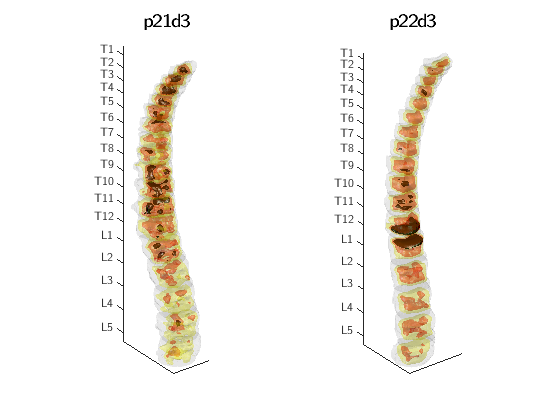

set(0,'DefaultTextFontname', 'LM Sans 12')
set(0,'DefaultAxesFontName', 'LM Sans 12')

figure();
subplot(1,2,1);
[vertStruct, vertIdxs] = createVertStruct([21,3]);

zs = zeros(512);
vert3d = cat(3, zs, vertStruct(1).pt_data, zs, ...
                    vertStruct(2).pt_data, zs, ...
                    vertStruct(3).pt_data, zs, ...
                    vertStruct(4).pt_data, zs, ...
                    vertStruct(5).pt_data, zs, ...
                    vertStruct(6).pt_data, zs, ...
                    vertStruct(7).pt_data, zs, ...
                    vertStruct(8).pt_data, zs, ...
                    vertStruct(9).pt_data, zs, ...
                    vertStruct(10).pt_data, zs, ...
                    vertStruct(11).pt_data, zs, ...
                    vertStruct(12).pt_data, zs, ...
                    vertStruct(13).pt_data, zs, ...
                    vertStruct(14).pt_data, zs, ...
                    vertStruct(15).pt_data, zs, ...
                    vertStruct(16).pt_data, zs, ...
                    vertStruct(17).pt_data, zs);

vert3d_nan = vert3d;
vert3d_nan(vert3d_nan == 0) = NaN;
[pt_hist_counts, pt_hist_edges] = histcounts(vert3d_nan);
pt_cdf = cdfFromHist(pt_hist_counts);
cdf_idx_1 = getClosestValueIdx(pt_cdf, 0.50);
iso_val_1 = pt_hist_edges(cdf_idx_1);
cdf_idx_2 = getClosestValueIdx(pt_cdf, 0.85);
iso_val_2 = pt_hist_edges(cdf_idx_2);
cdf_idx_3 = getClosestValueIdx(pt_cdf, 0.98);
iso_val_3 = pt_hist_edges(cdf_idx_3);

fv0 = isosurface(vert3d, 0.5);
fv1 = isosurface(vert3d, iso_val_1);
fv2 = isosurface(vert3d, iso_val_2);
fv3 = isosurface(vert3d, iso_val_3);

colormap("lines")
p0 = patch(fv0,'FaceColor', 'black','EdgeColor','none');
p0.FaceAlpha = 0.05;
p1 = patch(fv1,'FaceColor', 'yellow','EdgeColor','none');
p1.FaceAlpha = 0.2;
p2 = patch(fv2,'FaceColor', 'red','EdgeColor','none');
p2.FaceAlpha = 0.3;
p2 = patch(fv3,'FaceColor', 'black','EdgeColor','none');
p2.FaceAlpha = 1;
[zt, zl] = getVertTickLabels(vertIdxs);
zticks(zt);
zticklabels(zl);
xticks([]);
yticks([]);
view(3)
daspect([1,1,1/3])
axis tight
camlight
camlight(-80,-10)
lighting flat
title("\fontsize{14}p21d3");

subplot(1,2,2);
[vertStruct, vertIdxs] = createVertStruct([22,3]);

zs = zeros(512);
vert3d = cat(3, zs, vertStruct(1).pt_data, zs, ...
                    vertStruct(2).pt_data, zs, ...
                    vertStruct(3).pt_data, zs, ...
                    vertStruct(4).pt_data, zs, ...
                    vertStruct(5).pt_data, zs, ...
                    vertStruct(6).pt_data, zs, ...
                    vertStruct(7).pt_data, zs, ...
                    vertStruct(8).pt_data, zs, ...
                    vertStruct(9).pt_data, zs, ...
                    vertStruct(10).pt_data, zs, ...
                    vertStruct(11).pt_data, zs, ...
                    vertStruct(12).pt_data, zs, ...
                    vertStruct(13).pt_data, zs, ...
                    vertStruct(14).pt_data, zs, ...
                    vertStruct(15).pt_data, zs, ...
                    vertStruct(16).pt_data, zs, ...
                    vertStruct(17).pt_data, zs);

vert3d_nan = vert3d;
vert3d_nan(vert3d_nan == 0) = NaN;
[pt_hist_counts, pt_hist_edges] = histcounts(vert3d_nan);
pt_cdf = cdfFromHist(pt_hist_counts);
cdf_idx_1 = getClosestValueIdx(pt_cdf, 0.50);
iso_val_1 = pt_hist_edges(cdf_idx_1);
cdf_idx_2 = getClosestValueIdx(pt_cdf, 0.85);
iso_val_2 = pt_hist_edges(cdf_idx_2);
cdf_idx_3 = getClosestValueIdx(pt_cdf, 0.98);
iso_val_3 = pt_hist_edges(cdf_idx_3);

fv0 = isosurface(vert3d, 0.5);
fv1 = isosurface(vert3d, iso_val_1);
fv2 = isosurface(vert3d, iso_val_2);
fv3 = isosurface(vert3d, iso_val_3);

colormap("lines")
p0 = patch(fv0,'FaceColor', 'black','EdgeColor','none');
p0.FaceAlpha = 0.05;
p1 = patch(fv1,'FaceColor', 'yellow','EdgeColor','none');
p1.FaceAlpha = 0.2;
p2 = patch(fv2,'FaceColor', 'red','EdgeColor','none');
p2.FaceAlpha = 0.3;
p2 = patch(fv3,'FaceColor', 'black','EdgeColor','none');
p2.FaceAlpha = 1;
[zt, zl] = getVertTickLabels(vertIdxs);
zticks(zt);
zticklabels(zl);
xticks([]);
yticks([]);
view(3)
daspect([1,1,1/3])
axis tight
camlight
camlight(-80,-10)
lighting flat
title("\fontsize{14}p22d3");


% subplot(1,4,3);
% [vertStruct, vertIdxs] = createVertStruct([9,3]);
% 
% zs = zeros(512);
% vert3d = cat(3, zs, vertStruct(1).pt_data, zs, ...
%                     vertStruct(2).pt_data, zs, ...
%                     vertStruct(3).pt_data, zs, ...
%                     vertStruct(4).pt_data, zs, ...
%                     vertStruct(5).pt_data, zs, ...
%                     vertStruct(6).pt_data, zs, ...
%                     vertStruct(7).pt_data, zs, ...
%                     vertStruct(8).pt_data, zs, ...
%                     vertStruct(9).pt_data, zs, ...
%                     vertStruct(10).pt_data, zs, ...
%                     vertStruct(11).pt_data, zs, ...
%                     vertStruct(12).pt_data, zs, ...
%                     vertStruct(13).pt_data, zs, ...
%                     vertStruct(14).pt_data, zs, ...
%                     vertStruct(15).pt_data, zs, ...
%                     vertStruct(16).pt_data, zs, ...
%                     vertStruct(17).pt_data, zs);
% 
% vert3d_nan = vert3d;
% vert3d_nan(vert3d_nan == 0) = NaN;
% [pt_hist_counts, pt_hist_edges] = histcounts(vert3d_nan);
% pt_cdf = cdfFromHist(pt_hist_counts);
% cdf_idx_1 = getClosestValueIdx(pt_cdf, 0.50);
% iso_val_1 = pt_hist_edges(cdf_idx_1);
% cdf_idx_2 = getClosestValueIdx(pt_cdf, 0.85);
% iso_val_2 = pt_hist_edges(cdf_idx_2);
% cdf_idx_3 = getClosestValueIdx(pt_cdf, 0.98);
% iso_val_3 = pt_hist_edges(cdf_idx_3);
% 
% fv0 = isosurface(vert3d, 0.5);
% fv1 = isosurface(vert3d, iso_val_1);
% fv2 = isosurface(vert3d, iso_val_2);
% fv3 = isosurface(vert3d, iso_val_3);
% 
% colormap("lines")
% p0 = patch(fv0,'FaceColor', 'black','EdgeColor','none');
% p0.FaceAlpha = 0.05;
% p1 = patch(fv1,'FaceColor', 'yellow','EdgeColor','none');
% p1.FaceAlpha = 0.2;
% p2 = patch(fv2,'FaceColor', 'red','EdgeColor','none');
% p2.FaceAlpha = 0.3;
% p2 = patch(fv3,'FaceColor', 'black','EdgeColor','none');
% p2.FaceAlpha = 1;
% [zt, zl] = getVertTickLabels(vertIdxs);
% zticks(zt);
% zticklabels(zl);
% xticks([]);
% yticks([]);
% view(3)
% daspect([1,1,1/3])
% axis tight
% camlight
% camlight(-80,-10)
% lighting flat
% title("\fontsize{14}p9d3");
% 
% subplot(1,4,4);
% [vertStruct, vertIdxs] = createVertStruct([10,3]);
% 
% zs = zeros(512);
% vert3d = cat(3, zs, vertStruct(1).pt_data, zs, ...
%                     vertStruct(2).pt_data, zs, ...
%                     vertStruct(3).pt_data, zs, ...
%                     vertStruct(4).pt_data, zs, ...
%                     vertStruct(5).pt_data, zs, ...
%                     vertStruct(6).pt_data, zs, ...
%                     vertStruct(7).pt_data, zs, ...
%                     vertStruct(8).pt_data, zs, ...
%                     vertStruct(9).pt_data, zs, ...
%                     vertStruct(10).pt_data, zs, ...
%                     vertStruct(11).pt_data, zs, ...
%                     vertStruct(12).pt_data, zs, ...
%                     vertStruct(13).pt_data, zs, ...
%                     vertStruct(14).pt_data, zs, ...
%                     vertStruct(15).pt_data, zs, ...
%                     vertStruct(16).pt_data, zs, ...
%                     vertStruct(17).pt_data, zs);
% 
% vert3d_nan = vert3d;
% vert3d_nan(vert3d_nan == 0) = NaN;
% [pt_hist_counts, pt_hist_edges] = histcounts(vert3d_nan);
% pt_cdf = cdfFromHist(pt_hist_counts);
% cdf_idx_1 = getClosestValueIdx(pt_cdf, 0.50);
% iso_val_1 = pt_hist_edges(cdf_idx_1);
% cdf_idx_2 = getClosestValueIdx(pt_cdf, 0.85);
% iso_val_2 = pt_hist_edges(cdf_idx_2);
% cdf_idx_3 = getClosestValueIdx(pt_cdf, 0.98);
% iso_val_3 = pt_hist_edges(cdf_idx_3);
% 
% fv0 = isosurface(vert3d, 0.5);
% fv1 = isosurface(vert3d, iso_val_1);
% fv2 = isosurface(vert3d, iso_val_2);
% fv3 = isosurface(vert3d, iso_val_3);
% 
% colormap("lines")
% p0 = patch(fv0,'FaceColor', 'black','EdgeColor','none');
% p0.FaceAlpha = 0.05;
% p1 = patch(fv1,'FaceColor', 'yellow','EdgeColor','none');
% p1.FaceAlpha = 0.2;
% p2 = patch(fv2,'FaceColor', 'red','EdgeColor','none');
% p2.FaceAlpha = 0.2;
% p2 = patch(fv3,'FaceColor', 'black','EdgeColor','none');
% p2.FaceAlpha = 1;
% [zt, zl] = getVertTickLabels(vertIdxs);
% zticks(zt);
% zticklabels(zl);
% xticks([]);
% yticks([]);
% view(3)
% daspect([1,1,1/3])
% axis tight
% camlight
% camlight(-80,-10)
% lighting flat
% title("\fontsize{14}p10d3");